% Clear workspace and command window
clear;
clc;

% FOR DESKTOP: Read data from the Excel file
precip_data = readtable('One_Year_precip_EA011_May23_May24.csv');
SWC_data = readtable('One_Year_dSoilWC_EA011_May23_May24.csv');
drip_data = readtable ('Retime_NBC_Loggers_JANMAYdaily.csv');
water_budget = readtable('Copy_of_Rainfall_Loggers_PET_monthly_SUM.csv'); 

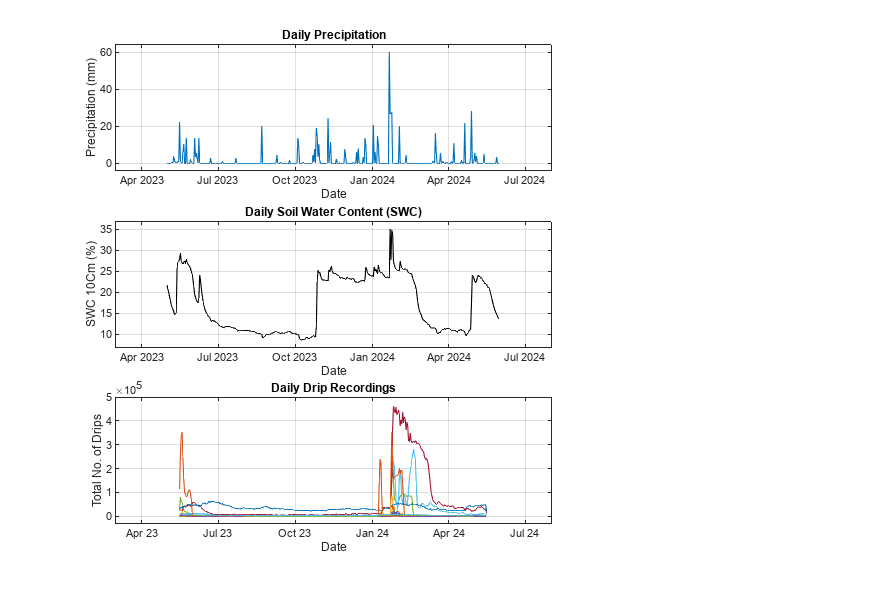



p_dates = precip_data {:, 1}; % Date is in column 1
rainfall = precip_data {:, 2}; % Rainfall is in column 2

s_dates = SWC_data {:, 1}; % Date is in column 1
SWC = SWC_data {:, 2}; % SWC is in column 2

d_dates = drip_data {:, 1}; % Date is in column 1
drip_count = drip_data{:, 2:21}; % Drip count is in columns 3 to 22

w_dates = water_budget {:, 1}; % Date is in column 1
p_et = water_budget{:, 4}; % P-ET is in column 4


% Create a figure
g = figure; clf;

% Make the figure larger if needed (optional)
set(g, 'Position', [100, 100, 1200, 800]);

% Plot 1 (Precipitation) - First plot occupies two columns in the first row
subplot(3, 3, [1, 2]); % [1,2] means this spans columns 1 and 2
plot(p_dates, rainfall); 
xlabel('Date');
ylabel('Precipitation (mm)');
title('Daily Precipitation');
grid on;
axis padded;

% Plot 2 (SWC) - Second plot occupies two columns in the second row
subplot(3, 3, [4, 5]); % [4,5] means this spans columns 1 and 2
plot(s_dates, SWC, 'k'); 
xlabel('Date');
ylabel('SWC 10Cm (%)');
title('Daily Soil Water Content (SWC)');
grid on;
axis padded;

% Plot 3 (Drip Recordings) - Third plot occupies two columns in the third row
subplot(3, 3, [7, 8]); % [7,8] means this spans columns 1 and 2
for i = 1:size(drip_data, 2)
    plot(d_dates, drip_count); 
    xlabel('Date');
    ylabel('Total No. of Drips');
    title('Daily Drip Recordings');
    grid on;
    axis padded;
end

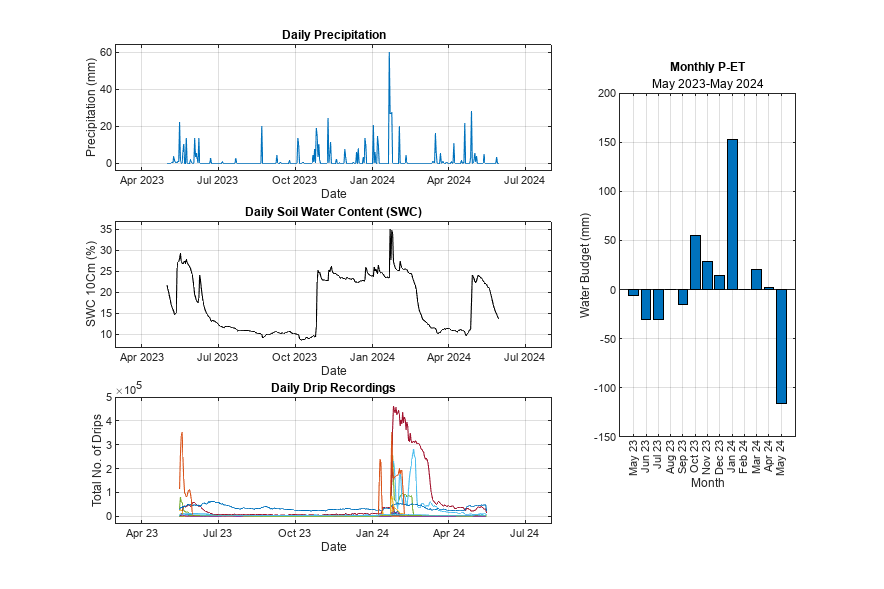



% Custom position for full column width and height
h4 = axes('Position', [0.7, 0.1, 0.2, 0.9]);  

% Plot the Monthly P-ET data
bar((1:1:13), p_et); 
xlabel('Month');
ylabel('Water Budget (mm)');
title('Monthly P-ET', 'May 2023-May 2024');
xtickangle(90);
xtick = {'May 23'; 'Jun 23'; 'Jul 23'; 'Aug 23'; 'Sep 23'; 'Oct 23'; 'Nov 23'; 'Dec 23'; 'Jan 24'; 'Feb 24'; 'Mar 24'; 'Apr 24'; 'May 24'};
set(gca, 'XTick', 1:1:13); 
set(gca, 'XTickLabel', xtick); 
grid on;

% Reduce the height by 20% after positioning the plot
pos = get(h4, 'Position');  % Get the current position
newHeight = pos(4) * 0.65;  % Reduce height by 80%

% Adjust the `bottom` position to move the graph up
% Calculate the new `bottom` position to shift the plot upwards
newBottom = pos(2) + (pos(4) - newHeight)*0.5;  % New bottom to shift plot upwards by 50% of the reduced space

% Apply the new position (with adjusted bottom and reduced height)
set(h4, 'Position', [pos(1), newBottom, pos(3), newHeight]);


% %-------
% % Plot 4 (P-ET) - This plot will occupy the third column (position 3, 6, and 9)
% subplot(3, 3, [3, 6, 9]); % Occupy the full third column spanning all rows
% bar((1:1:13), p_et); 
% xlabel('Months');
% ylabel('Water Budget (mm)');
% title('Monthly P-ET May 2023-2024');
% xtickangle(90);
% xtick = {'May 23'; 'Jun 23'; 'Jul 23'; 'Aug 23'; 'Sep 23'; 'Oct 23'; 'Nov 23'; 'Dec 23'; 'Jan 24'; 'Feb 24'; 'Mar 24'; 'Apr 24'; 'May 24'};
% set(gca, 'XTick', 1:1:13); 
% set(gca, 'XTickLabel', xtick); 
% grid on;
% %--------

% Save the figure
%saveas(g, 'Chapman_final_Fig2_Layout.png');

% Set the PaperPosition to include borders/margins around the figure
set(g, 'PaperPosition', [0, 0, 12, 8]); % Adjust the size as needed (e.g., 12x8 inches)
set(g, 'PaperSize', [12, 8]);            % Set the paper size to match the figure size

%exportgraphics(g, 'Chapman_final_Fig2_Layout15Res.png', 'Resolution', 1500);